clc; close all; clear;
saveDir = checkDir('/Users/Rishabh/Dropbox (MIT)/PUFFIN/Data/Other/Biot-Savart/');
if ~exist(saveDir,'dir')
    mkdir(saveDir)
end

## **Single Infinitely Long Wire**

**a) Create geometry**

I0 = 1e6; % Total current, A
BS = ArrayBiotSavart(I0); % Create Object
BS = BS.createPlanarArray(1,1e-3); % Call a planar array with only 1 wire

figure; % Show array
BS.showArray();
xlim(5e-3*[-1,1]); ylim(5e-3*[-1,1]); zlim(1*[0,1]);

**b) Point of Interest**

pts = [0, 0.1e-3, 0.5]; % Point coordinates, [m]
plot3(pts(1),pts(2),pts(3),'xr','MarkerSize',10,'LineWidth',3); hold on; % Plot point on array

**c) Solve for magnetic field at point of interest**

N = [5,10,25,50,100,200,400,800,1600,1600*2,10^4,5*10^4]; % Number of elements
BB = [];
for ii = 1:length(N)
    B = BS.getB(N(ii),pts); % Magnetic field, T
    BB = [BB; norm(B,2)]; % Magnetic field manitude, T
end

**d) Caluclate analytical field from ampere's law**

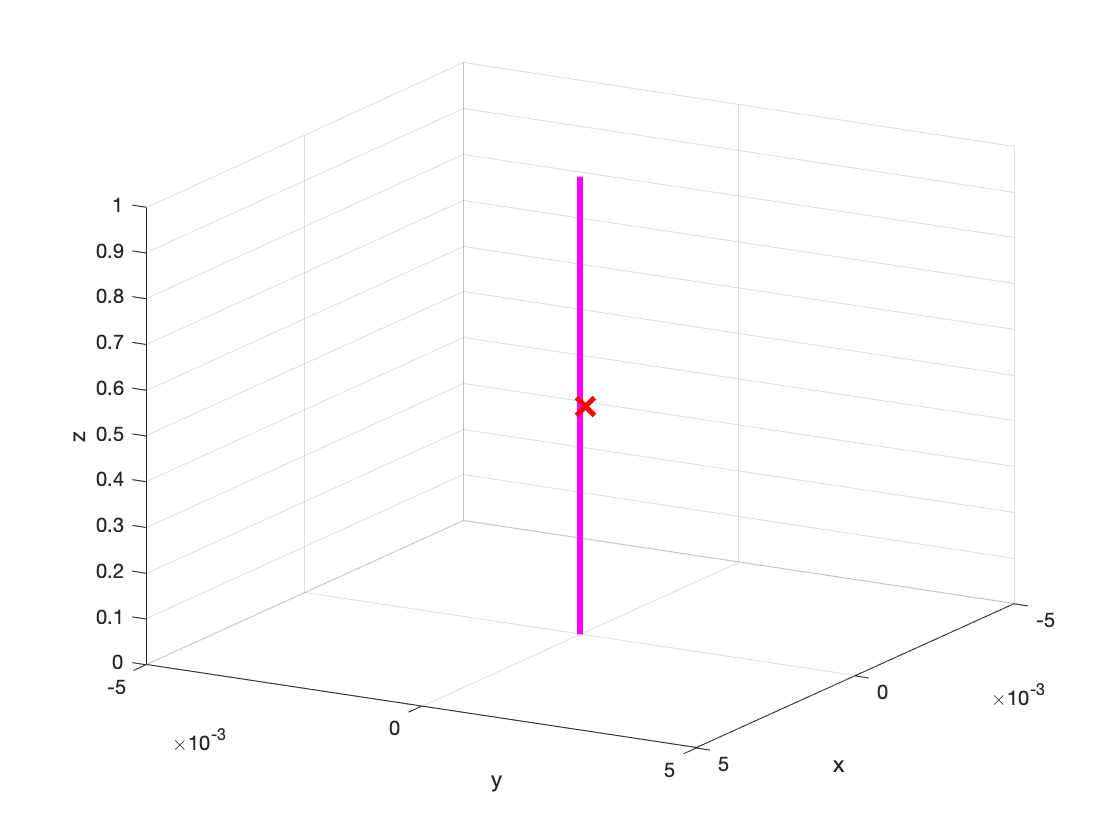

load physicalConstants-SI.mat mu0
rad_dist = norm(pts - [0,0,0.5],2); 
B_amp = mu0 * I0 / (2 * pi * rad_dist); % T

saveas(gcf,[saveDir, 'SingleWire-R-' num2str(rad_dist,2) '.png'])

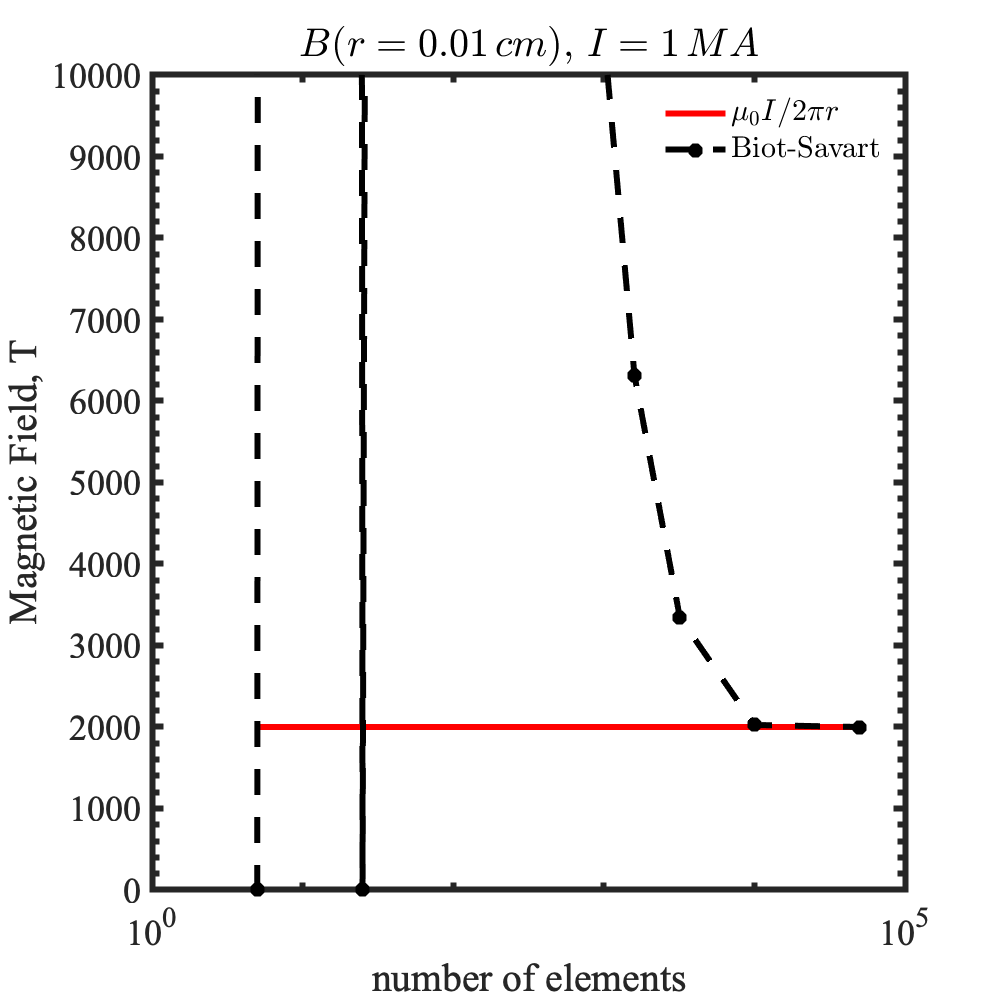


figure; % Compare analytical and numerical Biot-Savart result
semilogx(([N(1), N(end)]), B_amp* [1,1],'r-','LineWidth',3,'DisplayName','$\mu_0 I / 2 \pi r$'); hold on;
semilogx((N), BB,'*--','Color','k','LineWidth',3,'DisplayName','Biot-Savart'); hold on;
xlabel('number of elements'); ylabel('Magnetic Field, T'); 
formatPlots(500); ylim([0,B_amp*5]);
title(['$B(r = ' num2str( rad_dist * 1e2) '\, cm), \, I = ' num2str(I0/1e6) ' \, MA$'],'Interpreter','latex');
saveas(gcf,[saveDir, 'SingleWire-R-' num2str(rad_dist,2) '-Conv.png'])

## Imploding Wire Array

clc; close all; clear;
saveDir = checkDir('/Users/Rishabh/Dropbox (MIT)/PUFFIN/Data/Other/Biot-Savart/');
if ~exist(saveDir,'dir')
    mkdir(saveDir)
end

**a) Create Geometry**

I0 = 1e6; % Total current, A
BS = ArrayBiotSavart(I0); % Create Object
BS = BS.createImplodingArray(16,8e-3); % Call a cylindrical array with only 16 wires and 8mm radius

figure; % Show array
BS.showArray();
zlim(0.5+[-1e-2,1e-2]); 
axis square;

 **b) Point of Interest**

pts = [0, 10e-3, 0.5]; % Point coordinates, [m]
plot3(pts(1),pts(2),pts(3),'xr','MarkerSize',10,'LineWidth',3); hold on; % Plot point on array


**c) Solve for magnetic field at point of interest2mm**

N = 500;
B = BS.getB(N,pts); % Magnetic field, T

**d) Caluclate analytical field from ampere's law**

Ampere's law tells us that the mag. field goes as ~1/r with distance from the array center and only exists outside the array

load physicalConstants-SI.mat mu0
rad_dist = norm(pts - [0,0,0.5],2); 
B_amp = mu0 * I0 / (2 * pi * rad_dist); % T, in azimuthal direction

% Show solutions
fprintf('Bx [T] = %0.3f\n',B(1)); % T

Bx [T] = -20.652


fprintf('By [T] = %0.3f\n',B(2)); % T

By [T] = -0.000


fprintf('Bz [T] = %0.3f\n',B(3)); % T

Bz [T] = 0.000


fprintf('B (mag) [T] = %0.3f\n',norm(B,2)); % T

B (mag) [T] = 20.652


fprintf('B (Ampere) [T] = %0.3f\n',B_amp); % T

B (Ampere) [T] = 20.000


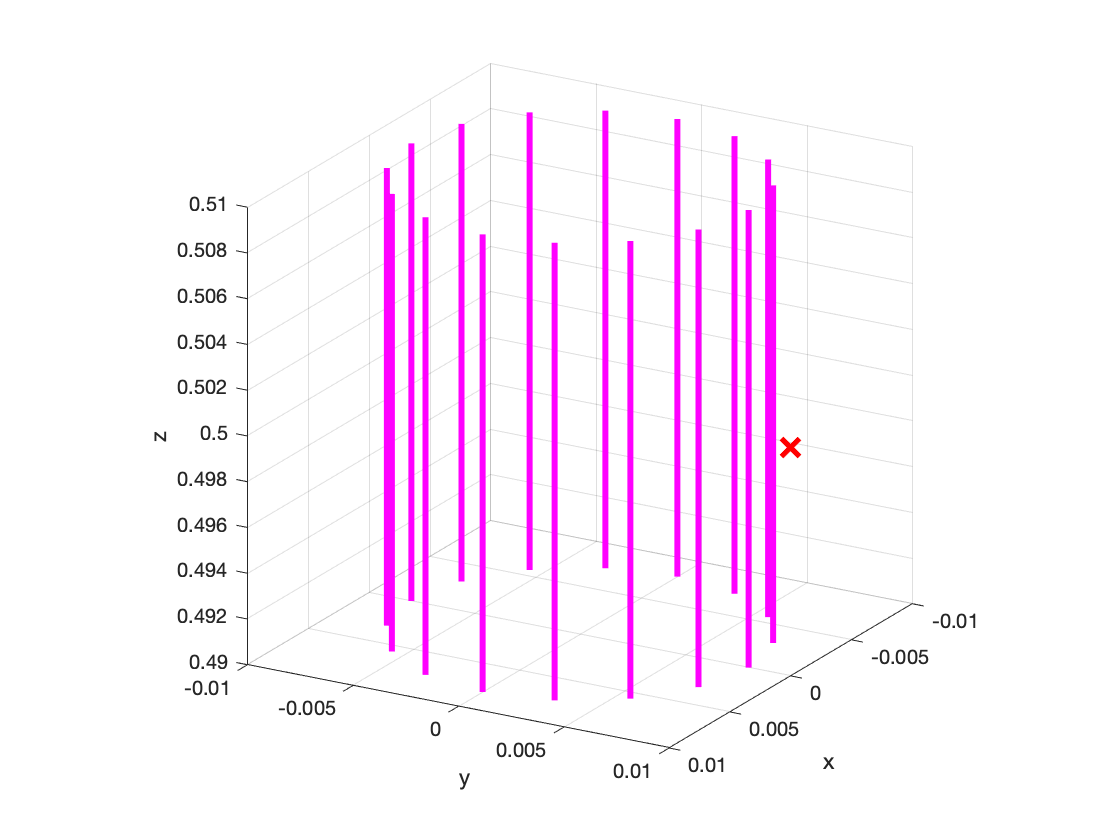


saveas(gcf,[saveDir, 'Imploder-R-' num2str(rad_dist,2) '.png'])

## Exploding Wire Array

**a) Create Geometry**

I0 = 1.4e6; % Total current, A
BS = ArrayBiotSavart(I0); % Create Object
BS = BS.createExplodingArray(16,8e-3,16*4,2e-3); % Call a cylindrical array with only 16 wires and 8mm radius, 2mm cathode

figure; % Show array
BS.showArray();
zlim(0.5+[-1e-2,1e-2]); 
axis square

 **b) Point of Interest**

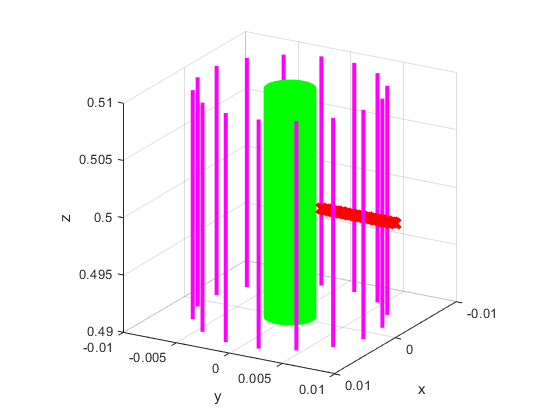

Yq = linspace(3,12,50); Yq = Yq .* 1e-3; % [m]
for ii = 1:length(Yq)
pts = [0, Yq(ii), 0.5]; % Point coordinates, [m]
plot3(pts(1),pts(2),pts(3),'xr','MarkerSize',10,'LineWidth',3); hold on; % Plot point on array
end

**c) Solve for magnetic field at point of interest**

N = 500; out = zeros(length(Yq),3);
parfor ii = 1:length(Yq)
    pts = [0, Yq(ii), 0.5]; % Point coordinates, [m]
    B(ii,:) = BS.getB(N,pts); % Magnetic field, T
end

**d) Caluclate analytical field from ampere's law**

Ampere's law tells us that the mag. field goes as ~1/r with distance from the array center and only exists inside the array

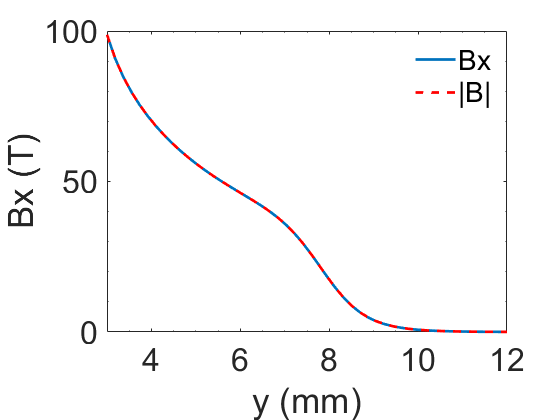

% load physicalConstants-SI.mat mu0
% rad_dist = norm(pts - [0,0,0.5],2); 
% B_amp = mu0 * I0 / (2 * pi * rad_dist); % T, in azimuthal direction
% 
% % Show solutions
% fprintf('Bx [T] = %0.3f\n',B(1)); % T
% fprintf('By [T] = %0.3f\n',B(2)); % T
% fprintf('Bz [T] = %0.3f\n',B(3)); % T
% fprintf('B (mag) [T] = %0.3f\n',norm(B,2)); % T
% fprintf('B (Ampere) [T] = %0.3f\n',B_amp); % T
Bmag = sqrt(B(:,1).^2 + B(:,2) + B(:,3).^2);
figure
plot(Yq*1e3,B(:,1),'LineWidth',2,'DisplayName','Bx'); hold on;
plot(Yq*1e3,Bmag,'r--','LineWidth',2,'DisplayName','|B|'); hold on;
xlabel('y (mm)'); ylabel('Bx (T)');
formatPlots();


save('BiotSavart.mat','B','Yq');

%saveas(gcf,[saveDir, 'Exploder-R-' num2str(rad_dist,2) '.png'])

### **Planar Array**

**a) Create Geometry**

I0 = 1e6; % Total current, A
BS = ArrayBiotSavart(I0); % Create Object
dx = 2*pi*20e-3/150; % [m], wire spacing
nwire = 15; % wire number
BS = BS.createPlanarArray(nwire,dx); % Call a planar array; match Z array current per wire and spacing
BS = BS.addCathode(nwire*4,dx/4,2e-3); % Place cathode 2 mm behind wires
figure; % Show array
BS.showArray();
zlim(0.5+[-1e-2,1e-2]); xlim(13e-3/2*[-1,1]); ylim(13e-3/2*[-1,1]);
axis square

 **b) Point of Interest**

% yq = -1e-3; % 100 um wires, set y-position just behind the wires
% xq = linspace(0,dx*(nwire-1),50) - dx*(nwire-1)/2; % x-positions, m
% P = [xq', yq * ones(size(xq')), 0.5 * ones(size(xq'))]; % All points
% B = zeros(size(P));
% 
% for ii = 1:size(P,1) % Show all points
%     pts = P(ii,:);
%     plot3(pts(1),pts(2),pts(3),'xr','MarkerSize',10,'LineWidth',3); hold on; % Plot point on array
% end
% 
% parfor ii = 1:size(P,1)
%     B(ii,:) = BS.getB(10^3,P(ii,:)); % Magnetic field, T
% end
% 
% Bmag = sqrt(B(:,1).^2 + B(:,2).^2 + B(:,3).^2);
% 
% saveas(gcf,[saveDir, 'Planar-R-' num2str(yq,2) '.png'])
% 
% figure;
% plot(xq*1e3,B(:,1),'-k','Linewidth',3,'DisplayName','$B_x$'); hold on;
% plot(xq*1e3,B(:,2),'--k','Linewidth',3,'DisplayName','$B_y$'); hold on;
% plot(xq*1e3,B(:,3),':k','Linewidth',3,'DisplayName','$B_z$'); hold on;
% plot(xq*1e3,Bmag,'--r','Linewidth',3,'DisplayName','Magnitude'); hold on;
% xlabel('x, mm'); ylabel('Magnetic Field, T');
% formatPlots(700);
% saveas(gcf,[saveDir, 'Imploder-R-' num2str(rad_dist,2) '-lineout.png'])


Get Magnetic Field Map

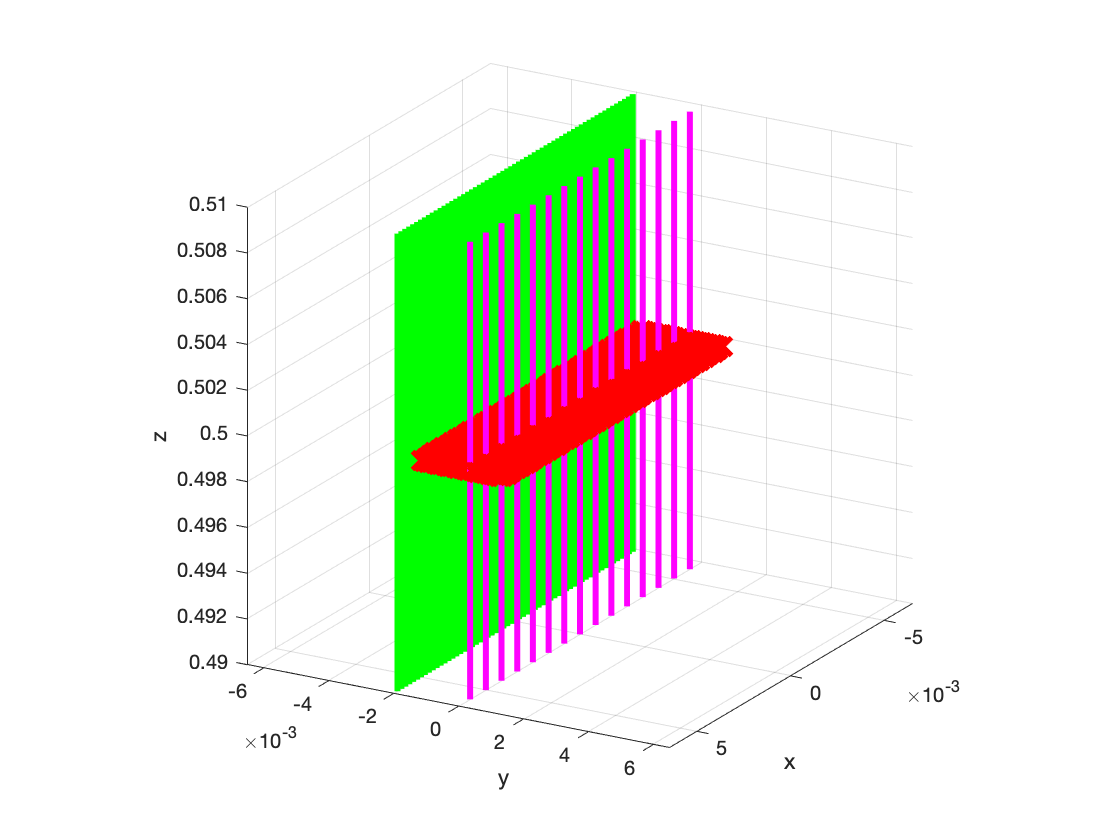

y = linspace(-1.5e-3,1e-3,25);
x = linspace(0,dx*(nwire-1),50) - dx*(nwire-1)/2; % x-positions, m
[xq, yq] = meshgrid(x,y);
P = [xq(:), yq(:), 0.5* ones(size(xq(:)))];

B = zeros(size(P));

for ii = 1:size(P,1) % Show all points
    pts = P(ii,:);
    plot3(pts(1),pts(2),pts(3),'xr','MarkerSize',10,'LineWidth',3); hold on; % Plot point on array
end


parfor ii = 1:size(P,1)
    B(ii,:) = BS.getB(10^4,P(ii,:)); % Magnetic field, T
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


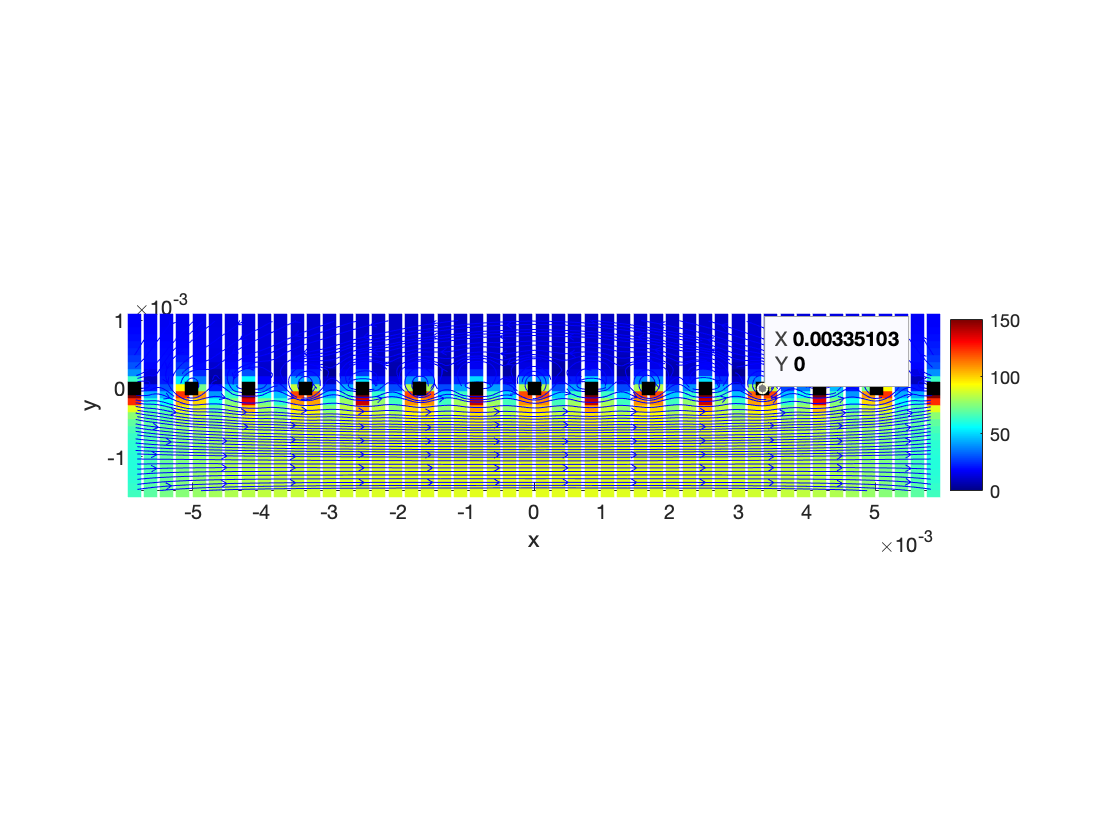


Bx = B(:,1); By = B(:,2); Bz = B(:,3); 
Bmag = sqrt(B(:,1).^2 + B(:,2).^2 + B(:,3).^2);

figure;
scatter(xq(:)*1e0,yq(:)*1e0,50*2,Bmag,'filled','s'); hold on;
xlabel('x'); ylabel('y');
axis equal; 
ylim([min(y),max(y)]);  xlim([min(x),max(x)]); 
colormap(inferno()); caxis([0,150]); colorbar();

Bx = reshape(Bx,size(xq));
By = reshape(By,size(xq));
h = streamslice(xq,yq,Bx,By,2);
set(h,'Color','g');
% quiver(xq,yq,Bx*0.001,By*0.001,'Color','w','AutoScale','off');

wp = BS.wire_pos;


scatter(xq(:)*1e0,yq(:)*1e0,50*2,Bmag,'filled','s',...
    'MarkerFaceAlpha',0.25); hold on;

scatter(wp(:,1)*1e0,wp(:,2)*1e0,50*1.5,'k','filled','c'); hold on;

saveas(gcf,[saveDir, 'Planar-R-' num2str(rad_dist,2) '-map.png']);

**c) Compare with cylindrical z array**

load physicalConstants-SI.mat mu0
rad_dist = 20e-3 - 100e-6; % [m]
I0 = 10e6;
B_amp = mu0 * I0 / (2 * pi * rad_dist); % T, in azimuthal direction
fprintf('B (Ampere) [T] = %0.3f\n',B_amp); % T

B (Ampere) [T] = 100.503
